# `Modeling Parachute Motion with Matlab `  

Now that we got some practice with using Matlab to model dynamic systems, let's try a slightly more challenging problem of a falling parachute.

Recall that:

- Air resistance/drag/friction played a major role in determining the dynamics in the falling parachute example.    

- We focused only on the dynamics in y-dimension (eliminate variables and equations for x-dimension)

- We modeled the friction forces as $F_f =\alpha \;V^2$where $\alpha \;=\frac{1}{2}\rho_{\textrm{air}} \;AC_D \;$is determined by the shape of the parachute ($A$ and $C_D$) and air density $\rho_{\textrm{air}} \;$.

### 
$$\begin{array}{l}
{\left(1\right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;V}_y \left(t+\Delta \;t\right)=V_y \left(t\right)+\left(\frac{\alpha \;}{m}{\left(V_y \left(t\right)\right)}^2 +g\right)\Delta \;t,\;\;\;\\
\left(2\right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;y\left(t+\Delta \;t\right)=y\left(t\right)+V_y \left(t\right)\Delta \;t,\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\\

\end{array}$$
 

To use the above equations in a Matlab program, the array subscripts must be integers, so you need to replace*** t+∆t*** with*** i+1***, and ***t*** with ***i***.

## `Task 1: Verify the projectile model with drag`

- Copy the code from S2, task 4 

- Remove variables and calculations in the x dimension -- we will ignore the x dimension in this simulation

- Change the equation for ***vy*** to the above equation

- Enter values for the parameters for your shopping bag parachute. With the addition of drag, you need to define some new variables, such as ***m*** and ***Cd*** and you will need to compute ***alpha***.

Here are the parameters that you measured for your shopping bag parachute

- d (m): diameter of shopping bag when open like a parachute

- m (kg): mass of parachute

- y(1) (m): initial height when dropping

- Vy(1) (m/sec): initial y velocity is zero

Here are the parameters that you need to include and calculate:

- 
$$\rho =1\ldotp 225\;\frac{\mathrm{kg}}{m^3 }$$


- 
$$A=\pi \frac{d^2 }{4}\;{\;\;\;\;\;\;\textrm{units}:m}^2$$


- 
$$C_D =1\ldotp 5$$


- 
$$\alpha =\frac{1}{2}\rho AC_D$$


Next steps:

- Export your parachute tracking data from Tracker. This should include ***t_exp, y_exp, and vy_exp*** data. Place the csv file in the same folder as this mlx file. 

- Run this program and see if it gives simulation results that are similar to the experimental results from Tracker.

The velocity should reach a "terminal" value, in which it stays relatively constant. If the simulation gives radically different results from the experiment, it may be due to a programming error. If the simulation gives somewhat different results, then the Matlab code is probably fine, then you may need to tweak the initial values of your parameters.

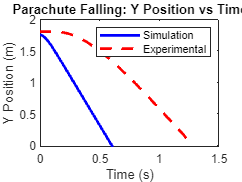

% copy your S2 task 4 code here and modify as described above
clc; clear; % Clean the workspace
close all; % Close all existing figures

% Define constants and initial conditions
g = -9.81;         % Acceleration due to gravity (m/s^2)
dt = 0.01;        % Time step (s)
Nsteps = 1000;    % Number of time steps

% Initialize arrays, make sure you do this before you creat you parameters
% or else you will have an index error (this is what happened last time
y = zeros(Nsteps, 1);
Vy = zeros(Nsteps, 1);
t = zeros(Nsteps, 1); % Initialize time array

% Parameters for the parachute and simulation
diameter = 0.29; % Diameter of the parachute when open (m)
m = 0.014; % Mass of the parachute (kg)
y(1) = 1.75; % Initial height when dropping (m) - set to match experimental data
Vy(1) = 0; % Initial y velocity is zero (m/s)

% Calculate additional parameters
density = 1.225; % Air density (kg/m^3)
A = pi*((diameter^2)/4); % Cross-sectional area of the parachute (m^2)
Cd = 1.5; % Drag coefficient
alpha = 0.5 * density * A * Cd;

% Initialize loop counter
i = 1;

while y(i) >= 0
    % Compute new velocity using the drag equation
    Vy(i + 1) = Vy(i) + ((alpha / m) * ((Vy(i))^2 + g) * dt);

    % Compute new position using updated velocity
    y(i + 1) = y(i) + Vy(i + 1) * dt;
    
    % Update time
    t(i + 1) = t(i) + dt;
    
    % Increment the loop counter
    i = i + 1;
end

% Trim arrays to only include data up to the point of impact
y = y(1:i);
Vy = Vy(1:i);
t = t(1:i);

% Import the experimental data from Tracker
Data = load('trackerparachute1.csv');
t_exp = Data(:, 1);
y_exp = Data(:, 2); % 2nd column contains experimental y data
Vy_exp = Data(:, 3); % 3rd column contains experimental Vy data

% Plot the simulation and experimental data for y vs t
figure;
plot(t, y, 'b-', 'LineWidth', 2, 'DisplayName', 'Simulation');
hold on;
plot(t_exp, y_exp, 'r--', 'LineWidth', 2, 'DisplayName', 'Experimental');
xlabel('Time (s)');
ylabel('Y Position (m)');
title('Parachute Falling: Y Position vs Time');
legend('Location', 'northeast');
hold off;

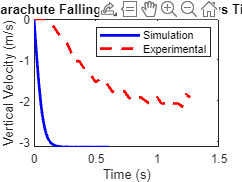


% Plot the simulation and experimental data for Vy vs t
figure;
plot(t, Vy, 'b-', 'LineWidth', 2, 'DisplayName', 'Simulation');
hold on;
plot(t_exp, Vy_exp, 'r--', 'LineWidth', 2, 'DisplayName', 'Experimental');
xlabel('Time (s)');
ylabel('Vertical Velocity (m/s)');
title('Parachute Falling: Vertical Velocity vs Time');
legend('Location', 'northeast');
hold off;

## `Task 2: Now, let's try this for a "real" parachute`

- Copy your code from task 1, but eliminate the last section where you plot experimental vs simulation data

Now that you have validated your simulation using the shoping bag parachute, here are the other parameters to use for your skydiver:

- d (m): diameter of shopping bag when open like a parachute

- m (kg): use the mass of your body (in kg) and add 25 lb (11.3 kg) to account for the weight of the parachute and other gear

- y(1) (m): assume that you are opening the parachute at 1000 ft, or 305 m

- Vy(1) (m/sec): initial y velocity is zero

Next steps

- Plot ***y vs t*** and ***vy vs t***. What is the terminal velocity? 

- Do research to identify a "reasonable" velocity for a safe landing (save this citation for your report). Did your simulation result in a reasonable value for a safe landing?

- Keep adjusting your value for d (parachute diameter) until you get a "reasonable" value without making the parachute so large in diameter so that it would be too heavy or cumbersome. 

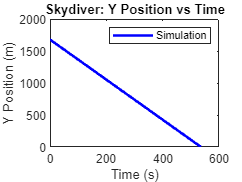

%your code starts here
clc; clear; % Clean the workspace
close all; % Close all existing figures

% Define constants and initial conditions
g = -9.81;         % Acceleration due to gravity (m/s^2)
dt = 0.01;         % Time step (s)
Nsteps = 1000;      % Number of time steps

% Initialize arrays
y = zeros(Nsteps, 1);
Vy = zeros(Nsteps, 1);
t = zeros(Nsteps, 1); % Initialize time array

% Parameters for the parachute and simulation
d = 6.095; % Diameter of the parachute when open (m) - placeholder value, adjust this based on your research. Research indicates that approximately 20 to 35 ft or 6.096 m to 10.668. 
m_body = 70; % Mass of your body (kg)
m_parachute = 25; % Mass of the parachute and other gear (kg)
m_total = m_body + m_parachute; % Total mass (kg)
y(1) = 1676.4; % Initial height when opening the parachute (m). From research, the average release height it anywhere from 5000 ft to 6000 ft. 
Vy(1) = 0; % Initial y velocity is zero (m/s)

% Calculate additional parameters
density = 1.225; % Air density (kg/m^3)
A = pi*((d^2)/4); % Cross-sectional area of the parachute (m^2)
Cd = 1.5; % Drag coefficient
alpha = 0.5 * density * A * Cd;

% Calculate terminal velocity using the provided formula
Vt = (2 * m_total * g) / (density * A * Cd);

% Initialize loop counter
i = 1;

while y(i) >= 0
    % Compute new velocity using the drag equation
    Vy(i + 1) = Vy(i) + ((alpha / m_total) * ((Vy(i))^2 + g) * dt);

    % Compute new position using updated velocity
    y(i + 1) = y(i) + Vy(i + 1) * dt;
    
    % Update time
    t(i + 1) = t(i) + dt;
    
    % Increment the loop counter
    i = i + 1;
end

% Trim arrays to only include data up to the point of impact
y = y(1:i);
Vy = Vy(1:i);
t = t(1:i);

% Find terminal velocity (from the formula)
terminal_velocity = Vt;

% Plot y vs t and Vy vs t
figure;
plot(t, y, 'b-', 'LineWidth', 2, 'DisplayName', 'Simulation');
xlabel('Time (s)');
ylabel('Y Position (m)');
title('Skydiver: Y Position vs Time');
legend('Location', 'northeast');

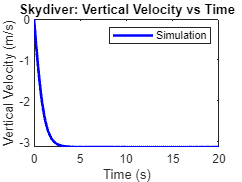


figure;
plot(t, Vy, 'b-', 'LineWidth', 2, 'DisplayName', 'Simulation');
xlabel('Time (s)');
xlim([0, 20]);
ylabel('Vertical Velocity (m/s)');
title('Skydiver: Vertical Velocity vs Time');
legend('Location', 'northeast');


% Display terminal velocity
fprintf('Terminal Velocity: %.2f m/s\n', terminal_velocity);

Terminal Velocity: -34.77 m/s


% In the line fprintf('Terminal Velocity: %.2f m/s\n', Vt);, the fprintf function is used to format and display the calculated terminal velocity (Vt) with two decimal places in the MATLAB Command Window. The message "Terminal Velocity: " is first printed, followed by the calculated value of Vt in meters per second, and a new line character ensures that the next output appears on a new line.


% Make sure you included these things: 
% Add your research findings about a reasonable velocity for a safe
% landing. Research indicates the a safe landing is approxiametly 130 mph
% or approximatly 58 m/s
% and whether the simulation results are reasonable based on your research.
% Adjust the parachute diameter (d) and repeat the simulation as needed.

